## Michaelis Menten - Enzyme Kinetics

### Model Equations

% define models
model1 = @(S, ks, vm) vm*S./(ks+S);
model2 = @(S, ks, vm) vm*S.^2./(ks^2+S.^2);

### Synthetic Data

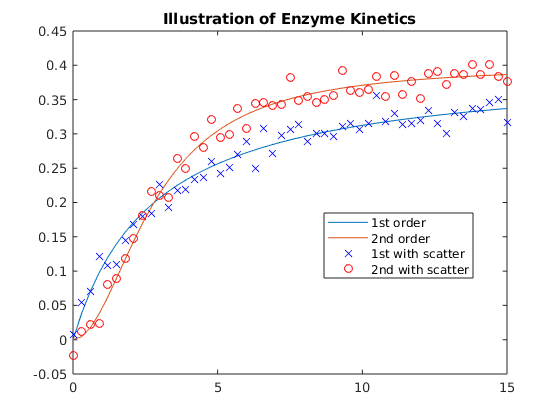

n = 51;
S = linspace(0, 15, n)';
vm = 0.4;
ks = 2.8;
sigma = .015;
v1 = model1(S, ks, vm) + sigma*randn(n,1);
v2 = model2(S, ks, vm) + sigma*randn(n,1);
cla
plot(S, model1(S, ks, vm), S, model2(S, ks, vm))
hold on
plot(S, v1, 'bx', S, v2, 'ro')
legend('1st order', '2nd order', '1st with scatter', '2nd with scatter', ...
    'location', 'best')
title('Illustration of Enzyme Kinetics')


% let's assume that our synthetic data follows a 2nd order model
v = v2;
% let's forget what model this was taken from
% use regression results to determine which model is more appropriate 
% (recall, we no longer know!)

### Fit data to to first order model

Z1 = [v -S];
y1 = -v.*S;

ZZ1 = Z1'*Z1;
Zy1 = Z1'*y1;

ab1 = ZZ1\Zy1;

ks1 = ab1(1)

ks1 = 2.4798

vm1 = ab1(2)

vm1 = 0.4558


cond(ZZ1)

ans = 1.0063e+04

### Fit data to to second order model

Z2 = [v -S.^2];
y2 = -v.*(S.^2);

ZZ2 = Z2'*Z2;
Zy2 = Z2'*y2;

ab2 = ZZ2\Zy2;

ks2 = ab2(1).^.5 % <--- there was a typo in class (no square root)

ks2 = 2.8102

vm2 = ab2(2)

vm2 = 0.4003


cond(ZZ2)

ans = 4.1521e+05

### Illustrate the Fits

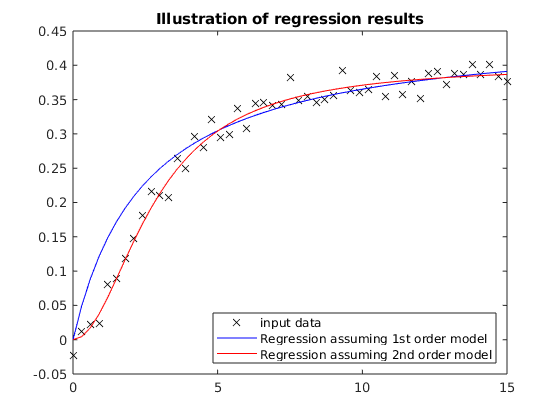

cla
plot(S,v,'kx')
hold on
plot(S,model1(S,ks1,vm1),'b')
plot(S,model2(S,ks2,vm2),'r')
title('Illustration of regression results')
legend('input data', ...
    'Regression assuming 1st order model', ...
    'Regression assuming 2nd order model', ...
    'location','southeast')

### Alternative approach

Fits work well, but are not necessarly well-conditioned. Alternatively, we can take the inverse of the model equations, i.e.


$$\frac{1}{v}=\frac{k_s+S}{v_m S}=\frac{k_s}{v_m}\frac{1}{S}+\frac{1}{v_m}=c_1\frac{1}{S}+d_1$$


for the first order model, and


$$\frac{1}{v}=\frac{k_s^2+S^2}{v_m S^2}=\frac{k_s^2}{v_m}\frac{1}{S^2}+\frac{1}{v_m}=c_2\frac{1}{S^2}+d_2$$


for the second order model.

% skip zero/negative entries (which wreak havoc for results)
ix = v>0 & S>0; % these are 'logical' indices for non-negative data
ix = ix & S>1; % further restrict as initial points spoil results
vinv = 1./v(ix); 
Sinv = 1./S(ix);

% modified expressions
Z1m = [Sinv ones(length(Sinv),1)];
% y1m = vinv % not needed (same for both models)

ZZ1m = Z1m'*Z1m;
Zy1m = Z1m'*vinv;

cd1 = ZZ1m\Zy1m;

vm1m = 1/cd1(2)

vm1m = 0.7598

ks1m = cd1(1)*vm1m

ks1m = 9.3129


cond(ZZ1m)

ans = 40.2982

% better conditioning, but results are worse!

% modified expressions
Z2m = [Sinv.^2 ones(length(Sinv),1)];
% y2m = vinv % not needed (same for both models)

ZZ2m = Z2m'*Z2m;
Zy2m = Z2m'*vinv;

cd2 = ZZ2m\Zy2m;

vm2m = 1/cd2(2)

vm2m = 0.3814

ks2m = (cd2(1)*vm2m)^.5

ks2m = 2.4857


cond(ZZ1m)

ans = 40.2982

% better conditioning, but results are worse!

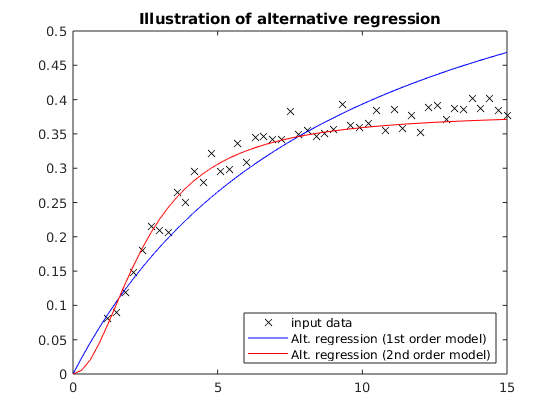

cla
plot(S(ix),v(ix),'kx')
hold on
plot(S,model1(S,ks1m,vm1m),'b') % 
plot(S,model2(S,ks2m,vm2m),'r')
title('Illustration of alternative regression')
legend('input data', ...
    'Alt. regression (1st order model)', ...
    'Alt. regression (2nd order model)', ...
    'location','southeast')

% results get better if a larger segment for small concentrations is
% skipped (e.g. only retaining S values larger than 2).